clear all
close all
F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

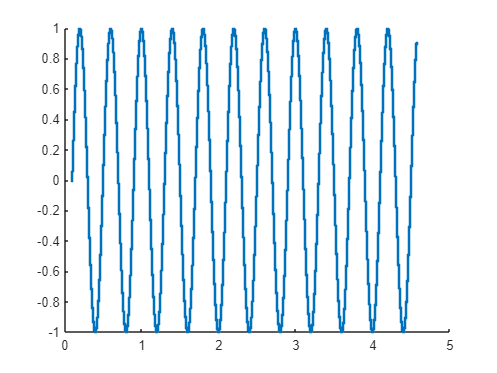

initial_0 = [1 0 0 0 0 0]';
initial_0 = ham_evolve(sigmax+sigmax^2,initial_0,0.0);
initial = ham_evolve(sigmax+sigmax^2,initial_0,pi/2);
%initial = initial_0;
a=0.5;
ham1 = +a*sigmax+1*sigmaz-10*sigmaz^2;
ham2 = 1*sigmax+1*sigmax^2;
timelist = ([0:0.0002:5].*pi+0.1*sqrt(1+a^2)*pi)/sqrt(1+a^2*1);
for i = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(i));
    final_state(:,i) = ham_evolve(ham2,precess_state,pi/2);
    %final_state(:,i) = precess_state;
end
pop_state = abs(final_state).^2;

%plot(timelist,pop_state(1,:));
%ylim([0.5 1]);
%plot(timelist,pop_state(6,:));
%ylim([-0.1 0.3]);
sz(:)=(pop_state(1,:)-pop_state(6,:))./(pop_state(1,:)+pop_state(6,:));
scatter(timelist/pi,sz,'.');
ylim([-1 1]);

freq=fft(sz)

freq = 1.0e+03 *

   0.2037 + 0.0000i   0.2053 - 0.0290i   0.2104 - 0.0595i   0.2195 - 0.0931i   0.2337 - 0.1321i   0.2547 - 0.1800i   0.2863 - 0.2427i   0.3353 - 0.3316i   0.4179 - 0.4722i   0.5796 - 0.7365i   1.0206 - 1.4404i   6.3942 - 9.9228i  -1.3428 + 2.2723i  -0.5803 + 1.0633i  -0.3598 + 0.7097i  -0.2556 + 0.5399i  -0.1952 + 0.4396i  -0.1560 + 0.3731i  -0.1287 + 0.3256i  -0.1086 + 0.2898i  -0.0932 + 0.2618i  -0.0812 + 0.2392i  -0.0715 + 0.2206i  -0.0636 + 0.2049i  -0.0570 + 0.1916i  -0.0515 + 0.1800i  -0.0468 + 0.1699i  -0.0427 + 0.1609i  -0.0392 + 0.1529i  -0.0361 + 0.1458i  -0.0334 + 0.1393i  -0.0310 + 0.1335i  -0.0288 + 0.1281i  -0.0269 + 0.1232i  -0.0252 + 0.1187i  -0.0237 + 0.1145i  -0.0222 + 0.1107i  -0.0210 + 0.1071i  -0.0198 + 0.1037i  -0.0187 + 0.1006i  -0.0178 + 0.0976i  -0.0169 + 0.0948i  -0.0160 + 0.0922i  -0.0153 + 0.0898i  -0.0145 + 0.0875i  -0.0139 + 0.0852i  -0.0133 + 0.0832i  -0.0127 + 0.0812i  -0.0122 + 0.0793i  -0.0117 + 0.0775i


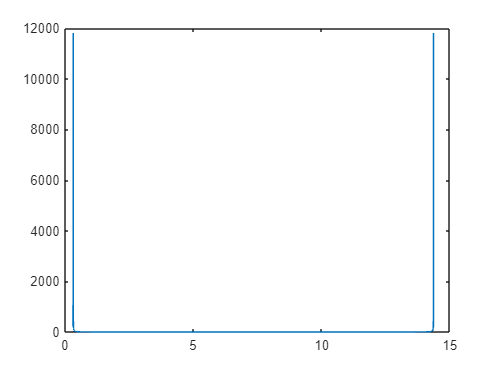

plot(timelist,abs(freq))

%xlim([2000 2010]);


function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end